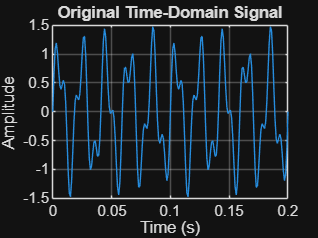

clc;
clear;
close all;

%% DIGITAL SIGNAL PROCESSING ANALYSIS
% Sampling, FFT, Decimation, Interpolation and FIR Filtering

%% 1. Signal Generation

Fs = 1000;                  % Sampling frequency (Hz)
T = 1;                      % Signal duration (seconds)

t = 0:1/Fs:T-1/Fs;

f1 = 50;                    % First frequency component
f2 = 120;                   % Second frequency component

x = sin(2*pi*f1*t) + 0.5*sin(2*pi*f2*t);

% Time-domain signal
figure;
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Time-Domain Signal');
grid on;
xlim([0 0.2]);

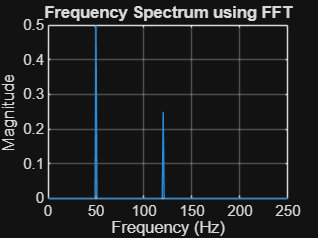



%% 2. FFT - Frequency Analysis

N = length(x);

X = fft(x);

frequency = (0:N-1)*(Fs/N);

magnitude = abs(X)/N;

figure;
plot(frequency, magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum using FFT');
grid on;
xlim([0 250]);

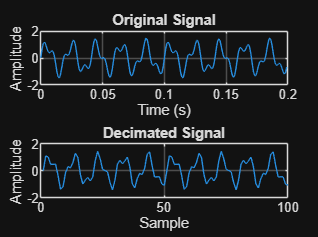



%% 3. Decimation (Downsampling)

D = 2;                      % Decimation factor

x_decimated = x(1:D:end);

Fs_decimated = Fs/D;

figure;

subplot(2,1,1);
plot(t(1:200), x(1:200));
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Signal');
grid on;

subplot(2,1,2);
plot(x_decimated(1:100));
xlabel('Sample');
ylabel('Amplitude');
title('Decimated Signal');
grid on;

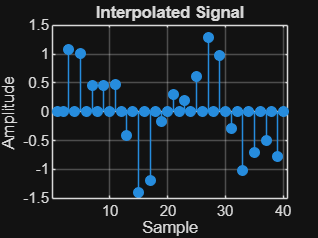



%% 4. Interpolation (Upsampling)

L = 2;                      % Interpolation factor

x_interpolated = zeros(1, length(x_decimated)*L);

x_interpolated(1:L:end) = x_decimated;

figure;
stem(x_interpolated(1:40), 'filled');
xlabel('Sample');
ylabel('Amplitude');
title('Interpolated Signal');
grid on;

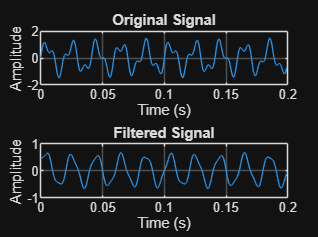



%% 5. FIR Low-Pass Filter

% Moving-average FIR filter
filter_length = 11;

h = ones(1, filter_length) / filter_length;

x_filtered = conv(x, h, 'same');

figure;

subplot(2,1,1);
plot(t(1:200), x(1:200));
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Signal');
grid on;

subplot(2,1,2);
plot(t(1:200), x_filtered(1:200));
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal');
grid on;

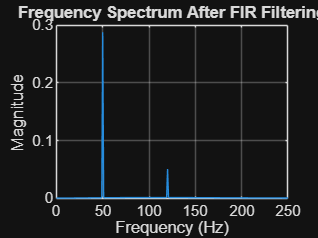



%% 6. FFT of Filtered Signal

X_filtered = fft(x_filtered);

filtered_magnitude = abs(X_filtered)/N;

figure;
plot(frequency, filtered_magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum After FIR Filtering');
grid on;
xlim([0 250]);



%% 7. Summary

disp('-------------------------------------------');

-------------------------------------------


disp(' DIGITAL SIGNAL PROCESSING ANALYSIS');

 DIGITAL SIGNAL PROCESSING ANALYSIS


disp('-------------------------------------------');

-------------------------------------------


disp(['Sampling Frequency: ', num2str(Fs), ' Hz']);

Sampling Frequency: 1000 Hz


disp(['Signal Frequencies: ', num2str(f1), ' Hz and ', num2str(f2), ' Hz']);

Signal Frequencies: 50 Hz and 120 Hz


disp(['Decimation Factor: ', num2str(D)]);

Decimation Factor: 2


disp(['Interpolation Factor: ', num2str(L)]);

Interpolation Factor: 2


disp(['FIR Filter Length: ', num2str(filter_length)]);

FIR Filter Length: 11


disp('FFT, decimation, interpolation and filtering completed.');

FFT, decimation, interpolation and filtering completed.
